clf; clear; close all;

% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 7);

% Specify sheet and range
opts.Sheet = "Problem 1";
opts.DataRange = "A3:G83";

% Specify column names and types
opts.VariableNames = ["ExperimentalData", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double"];

% Import the data
MAE378Homework2FILEFORSTUDENTS = readtable("C:\Users\nicholas\Downloads\MAE 378 Homework 2 FILE FOR STUDENTS.xlsx", opts, "UseExcel", false);

% Clear temporary variables
clear opts

% Display results
MAE378Homework2FILEFORSTUDENTS

MAE378Homework2FILEFORSTUDENTS = 81×7 table
    ExperimentalData     Var2        Var3        Var4      Var5     Var6      Var7   
    ________________    ______    __________    ______    ______    ____    _________

              0           0.25    5.6037e-05       NaN     0.529    2.16          NaN
        0.00025         1.0001     0.0002313    7.4805       NaN     NaN          NaN
         0.0005         3.0002    0.00076279    52.558    13.144     NaN          NaN
        0.00075         2.7503    0.00069083    7.8888       NaN     NaN          NaN
          0.001         5.5003     0.0015774    57.735       NaN     NaN          NaN
        0.00125         6.0004     0.0017618    40.945       NaN     NaN    0.0020556
         0.0015         8.250

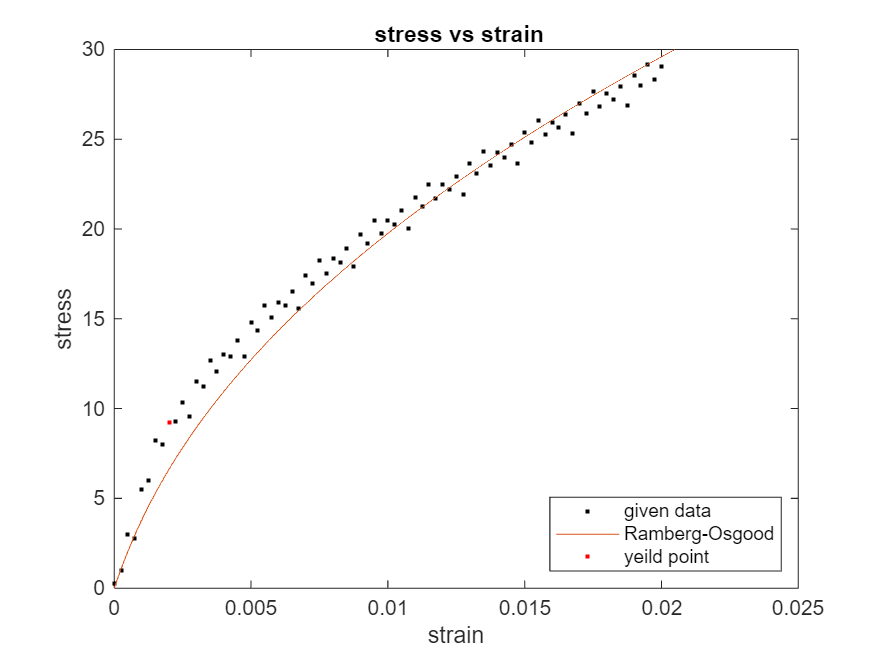



plot(MAE378Homework2FILEFORSTUDENTS,"ExperimentalData","Var2","LineStyleMode","manual","Marker",".",'Color','black','LineStyle','none')
hold on


alpha = 0.529;
n = 2.16;
aproximation = @(stress) stress./4497.15 + alpha.*stress./4497.15.*(stress./9.2443).^(n-1);
stress = 0:0.0001:30;
strain = aproximation(stress);


%plot(MAE378Homework2FILEFORSTUDENTS,"Var3","Var2","LineStyle","-",'Color','m')
plot(strain,stress)
plot(0.002,9.2443,'r.')
title(' stress vs strain');
xlabel('strain');
ylabel('stress')
legend('given data','Ramberg-Osgood','yeild point','Location','southeast')

figure(1)

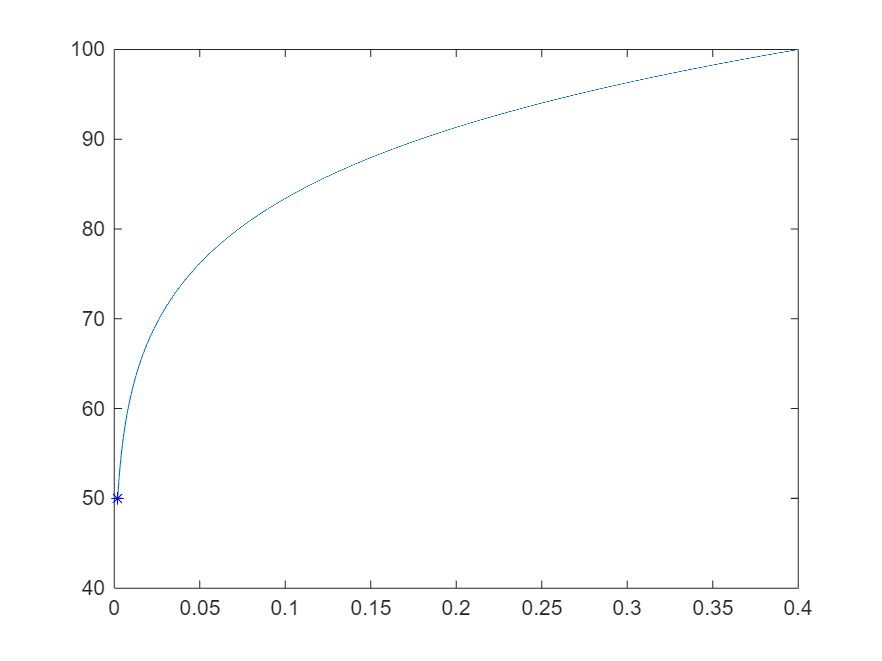

clf;

strain1 = 0.002:0.0001:0.4;
k = 112.73;
n1 = 0.130824;

stress1 = k.*strain1.^n1;

plot(strain1,stress1)
hold on;
plot(0.002,50,'b*')

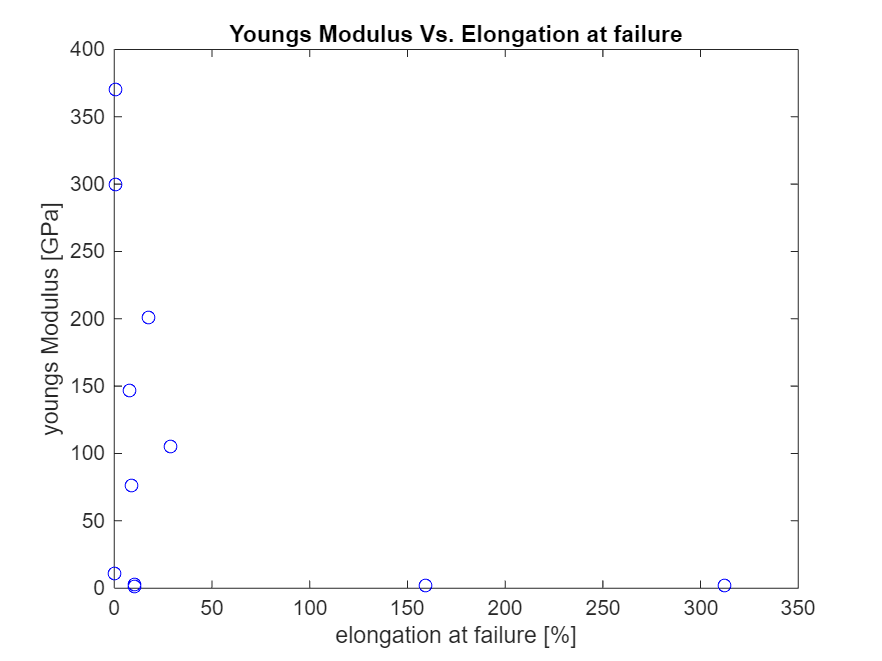

clf;

elongation = [0.02 10.3 7.98 17.7 0.8 0.8 10.1 8.85 28.8 159 312];
youngsMod = [11.2 0.995 147 201 370 300 2.93 76.3 105 1.69 2.14];

plot(elongation,youngsMod,'bo')
hold off
title('Youngs Modulus Vs. Elongation at failure')
xlabel('elongation at failure [%]')
ylabel('youngs Modulus [GPa]')

% Set up the Import Options and import the data
opts2 = spreadsheetImportOptions("NumVariables", 6);

% Specify sheet and range
opts2.Sheet = "Problem 4";
opts2.DataRange = "A1:F62";

% Specify column names and types
opts2.VariableNames = ["T__C_", "HeatFlow_W_", "Var3", "SampleMass_", "x0_0005", "g"];
opts2.VariableTypes = ["double", "double", "string", "string", "double", "string"];

% Specify variable properties
opts2 = setvaropts(opts2, ["Var3", "SampleMass_", "g"], "WhitespaceRule", "preserve");
opts2 = setvaropts(opts2, ["Var3", "SampleMass_", "g"], "EmptyFieldRule", "auto");

% Import the data
MAE378Homework2FILEFORSTUDENTS12 = readtable("C:\Users\nicholas\Downloads\MAE 378 Homework 2 FILE FOR STUDENTS 1.xlsx", opts2, "UseExcel", false);

% Convert to output type
T__C_ = MAE378Homework2FILEFORSTUDENTS12.T__C_;
HeatFlow_W_ = MAE378Homework2FILEFORSTUDENTS12.HeatFlow_W_;
Var3 = MAE378Homework2FILEFORSTUDENTS12.Var3;
SampleMass_ = MAE378Homework2FILEFORSTUDENTS12.SampleMass_;
x0_0005 = MAE378Homework2FILEFORSTUDENTS12.x0_0005;
g = MAE378Homework2FILEFORSTUDENTS12.g;

% Clear temporary variables
clear MAE378Homework2FILEFORSTUDENTS12

% Clear temporary variables
clear opts2

% Display results
T__C_, HeatFlow_W_, Var3, SampleMass_, x0_0005, g

T__C_ =    NaN
     0
     1
     2
     3
     4
     5
     6
     7
     8


HeatFlow_W_ =        NaN
    0.0020
    0.0020
    0.0020
    0.0020
    0.0020
    0.0020
    0.0020
    0.0020
    0.0020


Var3 = 62×1 string array
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""


SampleMass_ = 62×1 string array
    "Sample Mass:"
    "Rate:"
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""


x0_0005 =     0.0005
    1.0000
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


g = 62×1 string array
    "g"
    "°C/min"
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""


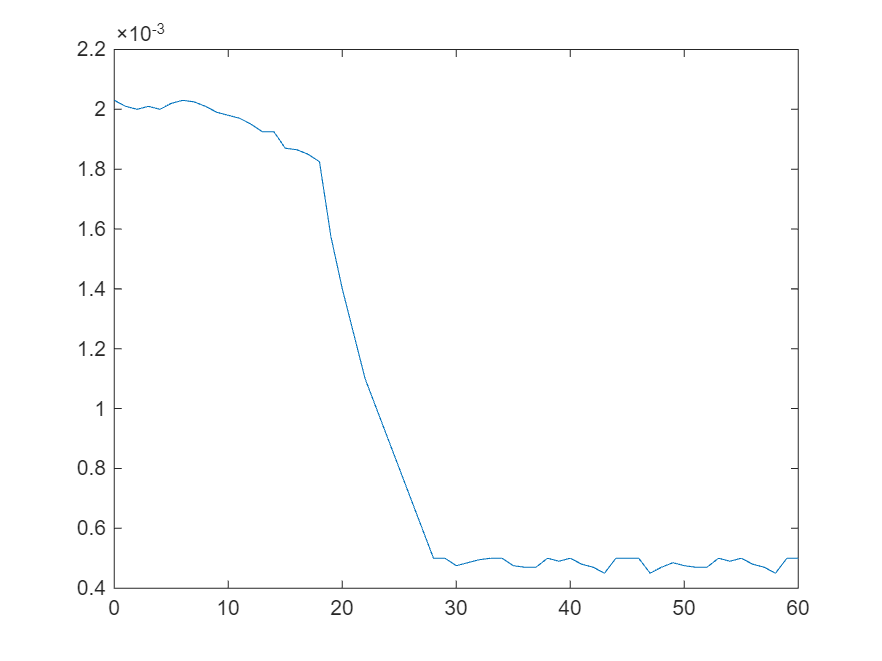

plot(T__C_,HeatFlow_W_)


cp = HeatFlow_W_./(1/60);
cp(1)=cp(2);
cp = cp./0.0005

cp =   243.6000
  243.6000
  241.2000
  240.0000
  241.2000
  240.0000
  242.4000
  243.6000
  243.0000
  241.2000


cp1 = [223.8000 222.0000 219.0000 189.0000 168.0000 150.0000 132.0000 120.0000 108.0000 96.0000 84.0000]

cp1 =   223.8000  222.0000  219.0000  189.0000  168.0000  150.0000  132.0000  120.0000  108.0000   96.0000   84.0000


t1 = [18 19 20 21 22 23 24 25 26 27 28];
s = cp1./t1;
trapz(cp1)

ans = 1.5579e+03

trapz(s)

ans = 71.5184

% Set up the Import Options and import the data
opts3 = spreadsheetImportOptions("NumVariables", 3);

% Specify sheet and range
opts3.Sheet = "Problem 5";
opts3.DataRange = "A2:C1602";

% Specify column names and types
opts3.VariableNames = ["x2_theta_deg_", "Intensity_cps_", "TiO2_Terpeniol_2_02_22_2019"];
opts3.VariableTypes = ["double", "double", "string"];

% Specify variable properties
opts3 = setvaropts(opts3, "TiO2_Terpeniol_2_02_22_2019", "WhitespaceRule", "preserve");
opts3 = setvaropts(opts3, "TiO2_Terpeniol_2_02_22_2019", "EmptyFieldRule", "auto");

% Import the data
MAE378Homework2FILEFORSTUDENTS14 = readtable("C:\Users\nicholas\Downloads\MAE 378 Homework 2 FILE FOR STUDENTS 1.xlsx", opts3, "UseExcel", false);

% Convert to output type
x2_theta_deg_ = MAE378Homework2FILEFORSTUDENTS14.x2_theta_deg_;
Intensity_cps_ = MAE378Homework2FILEFORSTUDENTS14.Intensity_cps_;
TiO2_Terpeniol_2_02_22_2019 = MAE378Homework2FILEFORSTUDENTS14.TiO2_Terpeniol_2_02_22_2019;

% Clear temporary variables
clear MAE378Homework2FILEFORSTUDENTS14

% Clear temporary variables
clear opts3

% Display results
x2_theta_deg_, Intensity_cps_, TiO2_Terpeniol_2_02_22_2019

x2_theta_deg_ =    10.0000
   10.0500
   10.1000
   10.1500
   10.2000
   10.2500
   10.3000
   10.3500
   10.4000
   10.4500


Intensity_cps_ =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


TiO2_Terpeniol_2_02_22_2019 = 1601×1 string array
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""


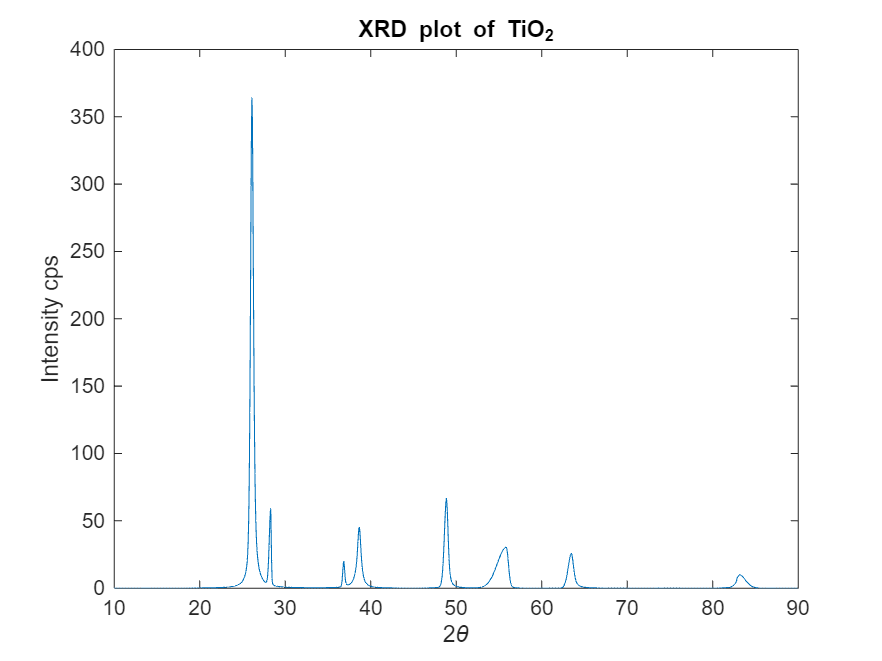

plot(x2_theta_deg_,Intensity_cps_)
title('XRD plot of TiO_2')
xlabel('2\theta')
ylabel('Intensity cps')